# Fit of baseline and phase corrected data from 2021-06-28

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210628';
load([Opt.LFolder, '\cwEDMR_2021_06_28.mat']);
[~, ncw] = size(x);

#### Fit

SysDb = struct(g = [2.0079 2.0061 2.0034], ...
    gStrain = [0.0054 0.0022 0.0018], ...
    lw = [0.500 1.389], ...
    Nucs = 'Si', A = [151 269]);
VaryDb = struct( ...
    lw = SysDb.lw);

SysV = struct(g = 2.01, ...
    gStrain = 0.0098, ...
    lw = [.5 0.526], ...
    weight = 0.54);
VaryV = struct( ...
    lw = SysV.lw, ...
    weight = SysV.weight);

SysC = struct(g = 2.0044, ...
    lw = [0 0.5], ...
    weight = 0.3);
VaryC = struct(...
    lw = SysC.lw, ...
    weight = SysC.weight);

SysTE = struct(g = 2.0077, ...
    gStrain = 0.0036, ...
    lw = [18.1 0], ...
    weight = 1);
VaryTE = struct(...
    lw = SysTE.lw, ...
    weight = SysC.weight);

Exp.mwFreq = 9.6055875; % GHz

Sys = {SysDb, SysV};
Vary = {VaryDb, VaryV};

% esfit(y(:, icw), @pepper, {Sys, Exp}, {Vary})

wbar = waitbar(0, 'Performing least-square fitting', ...
    'Name', 'esfit in progress');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    Exp.Range = [min(x_) max(x_)];
    Exp.mwFreq = cwStruct(icw).Params(1).MWFQ*1e-9;
    Fit_ = esfit(y_, @pepper, {Sys, Exp}, {Vary});
    
    % Simulate components separately.
    bestSysDb_ = Fit_.argsfit{1, 1}{1, 1};
    bestSysV_ = Fit_.argsfit{1, 1}{1, 2};
    Exp_ = Fit_.argsfit{1, 2};
    Fit_.DbFit = pepper(bestSysDb_, Exp_)*Fit_.scale;
    Fit_.VFit = pepper(bestSysV_, Exp_)*Fit_.scale;

    % Store in structure
    if icw == 1
        Fit = repmat(Fit_, 1, ncw);
    else
        Fit(icw) = Fit_;
    end
    waitbar(icw/ncw, wbar)
end

-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepper
Number of fit parameters: 3
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 3 active parameters...
iteration   1: value 2.14261e-02   edge 1.00000e-01   initial simplex
iteration   2: value 2.14261e-02   edge 2.77800e-01   contraction outside
iteration   3: value 2.14261e-02   edge 1.82413e-01   contraction inside
iteration   4: value 2.14261e-02   edge 1.82413e-01   contraction inside
iteration   5: value 2.14261e-02   edge 1.46617e-01   reflection
iteration   6: value 2.14261e-02   edge 8.43452e-02   contraction inside
iteration   7: value 2.11816e-02   edge 1.09949e-01   reflection
iteration   8: value 2.11816e-02   edge 1.09949e-01   contraction inside
iteration   9: value 2.11816e-02   edge 6.89799e-0

delete(wbar)

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    save([Opt.SFolder, '\fit_2021_06_28'], 'x', 'y', 'cwStruct', 'Fit');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end

## Figure 

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

grayC = '#b2beb5';

(1.1 148), (1.2 217), (1.25 256), (1.3 294)

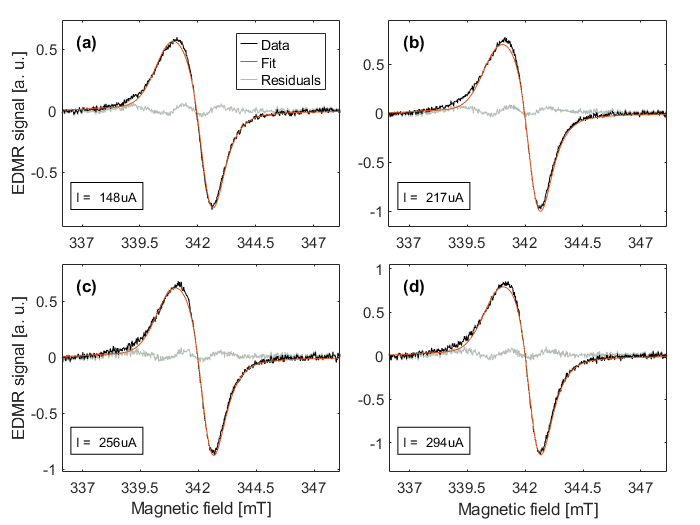

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    h(1) = plot(x(:, icw), y(:, icw), 'Color', [0 0 0]);
    hold on
    h(2) = plot(x(:, icw), Fit(icw).fit);
    h(3) = plot(x(:, icw), y(:, icw) - Fit(icw).fit, 'Color', grayC);
    
    set(gca,'Children',[h(2) h(1) h(3)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y(:, icw), 0.1));

    if icw == ncw - 3 || icw == ncw - 1
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end
annotateSubplotId(tL)
legendFirstTile(tL, ["Data", "Fit", "Residuals"], [h(1) h(2) h(3)]);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
exportFig(gcf, Opt.SFolder, '/2021-06-28 cwEDMR fit', '.png', 'residuals')

Graphics not exported


## Figure fit components

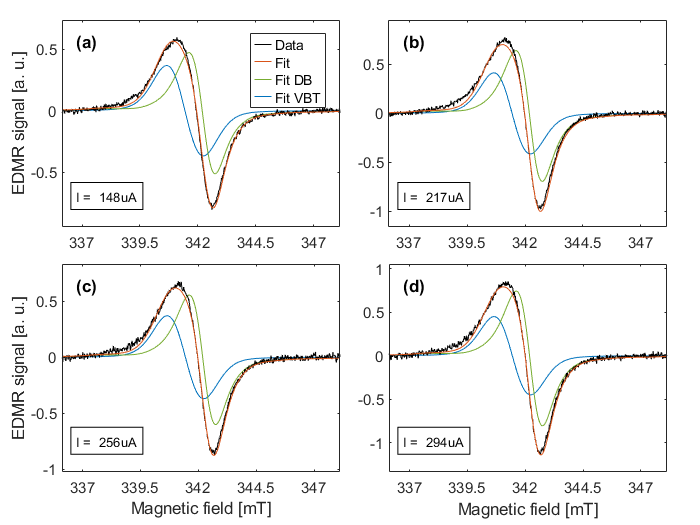

greenC = '#77AC30';
firstC = '#0072BD';
figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    nexttile
    x_ = x(:, icw); y_ = y(:, icw);
    h(1) = plot(x_, y_, 'Color', [0 0 0]);
    hold on
    h(2) = plot(x_, Fit(icw).fit);
    h(3) = plot(x_, Fit(icw).DbFit, 'Color', greenC);
    h(4) = plot(x_, Fit(icw).VFit, 'Color', firstC);

    set(gca,'Children',[h(2) h(1) h(3) h(4)]) % [top, middle, bottom]
    set(gca, "Layer", "top")

    xticks(337:2.5:347); yticks(-1:0.5:1);
    xlim(setAxLim(x(:, icw), 0)); ylim(setAxLim(y(:, icw), 0.1));

    if icw == ncw - 3 || icw == ncw - 1
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    annStr = {sprintf('I = %s', cwStruct(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black'); 
end
lgd = legendFirstTile(tL, {'Data', 'Fit', 'Fit DB', 'Fit VBT'}, h);
lgd.NumColumns = 1;
annotateSubplotId(tL)


exportStr = input('Export graphics with fit components? y/n\n', 's');
if strcmp(exportStr, 'y')
    Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
    exportgraphics(gcf, [Opt.SFolder, '/2021-06-28 cwEDMR fit components.png'])
else
    disp('Graphics not exported')
end

Graphics not exported


#### "DeltaI"/I is not constant

Idc = [148 217 256 294]; % uA
figure('Visible', 'off')
hold on
for icw = 1:ncw
    plot(x(:, icw), y(:, icw)/Idc(icw))
end

## ppAmp vs Vbias

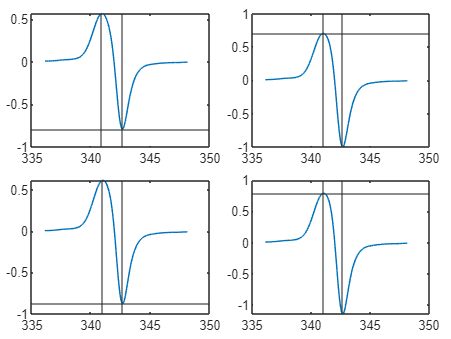

Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Data analysis Elexsys';
Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';
load([Opt.LFolder, '\fit_2021_06_28']);
[~, ncw] = size(x);

[ppAmp, yMax, yMin, xMax, xMin] = deal(zeros(1, ncw));

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');
for icw = 1:ncw
    x_ = x(:, icw); y_ = y(:, icw);
    yFit_ = Fit(icw).fit; yDb_ = Fit(icw).DbFit; yV_ = Fit(icw).VFit;
    [ppAmp(icw), yMax(icw), yMin(icw), xMax(icw), xMin(icw)] = getPeakToPeakAmp(x_, yFit_);
    
    nexttile
    plot(x_, yFit_)
    hold on
    yline(yMax(icw)); yline(yMin(icw));
    xline(xMax(icw)); xline(xMin(icw));
end

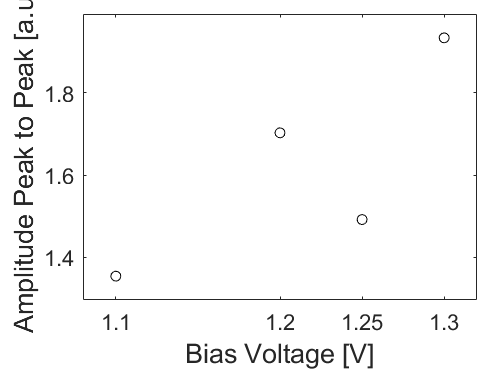

figure()
tL = tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact');

ax = nexttile(1);
Vbias = [1.1, 1.2, 1.25, 1.3]; ppAmpCut = ppAmp;
h(1) = plot(Vbias, ppAmpCut, 'o', 'Color', 'black');


xticks(Vbias); 
xlim(setAxLim(Vbias, 0.1)); ylim(setAxLim(ppAmpCut, 0.1));

labelAxesFig(tL, "Bias Voltage [V]", "Amplitude Peak to Peak [a.u.]")

exportFig(gcf, Opt.SFolder, "_ppAmp", "pdf");

Graphics not exported


exportFig(gcf, Opt.SFolder, "_ppAmp", "png");

Graphics not exported
